# Numerische Differentation

eps = 10^(-16);
hEinseitig = (12*eps)^(1/2) % Die Konstanten M2, U1, M0 werden als 1 angenommen

hEinseitig = 3.4641e-08

hZweiseitig = (9*eps)^(1/3) % Die Konstanten M2, U1, M0 werden als 1 angenommen

hZweiseitig = 9.6549e-06

x=1;
h = logspace(-9,-1);

## Polynomfunktion

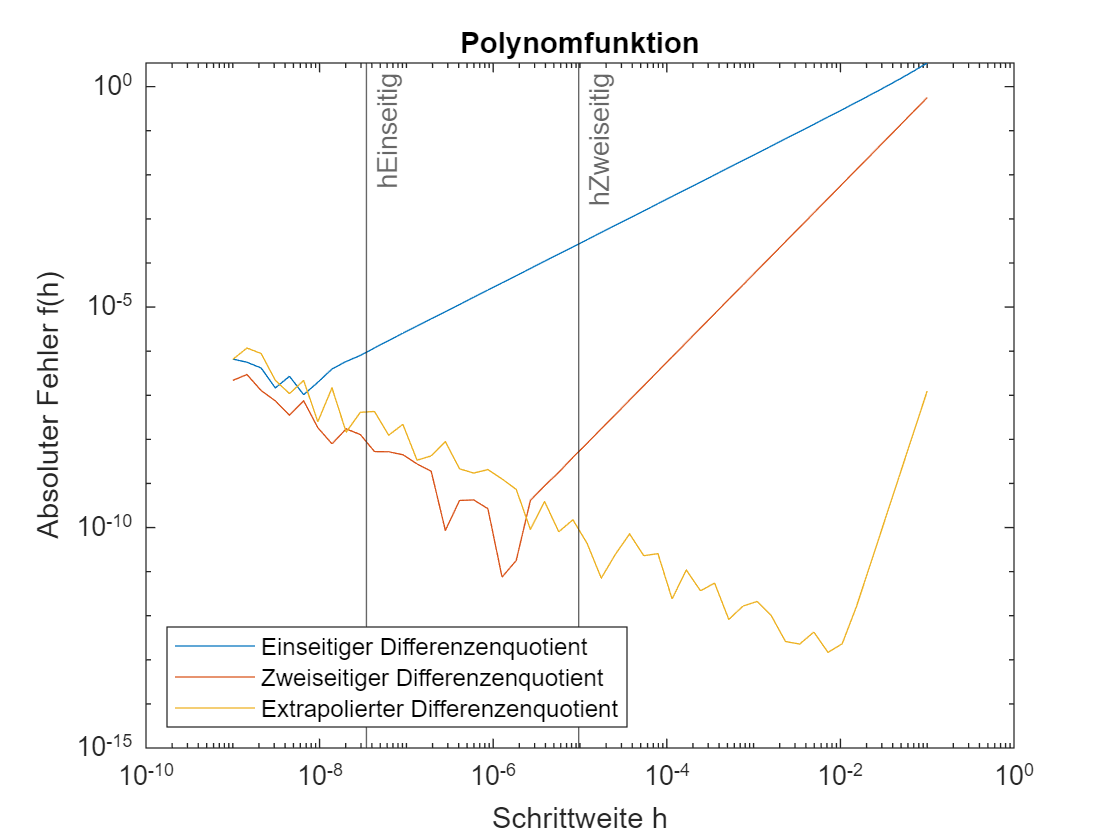

f = @func3;
fa = @func3Strich;

AbsFehlerEinseitig = FehlerEinseitigerDifferenzenquotient(f,fa,h,x);
AbsFehlerZweiseitig = FehlerZweiseitigerDifferenzenquotient(f,fa,h,x);
AbsFehlerExtrapoliert = FehlerExtrapolierterDifferenzenquotient(f,fa,h,x);

loglog(h,AbsFehlerEinseitig)
hold on 
loglog(h,AbsFehlerZweiseitig)
loglog(h,AbsFehlerExtrapoliert)
xline(hEinseitig,'-',{'hEinseitig'});
xline(hZweiseitig,'-',{'hZweiseitig'});
title('Polynomfunktion')
legend({'Einseitiger Differenzenquotient', 'Zweiseitiger Differenzenquotient', 'Extrapolierter Differenzenquotient'},'Location','southwest')
ylabel('Absoluter Fehler f(h)')
xlabel('Schrittweite h')
hold off

## Exponentialfunktion

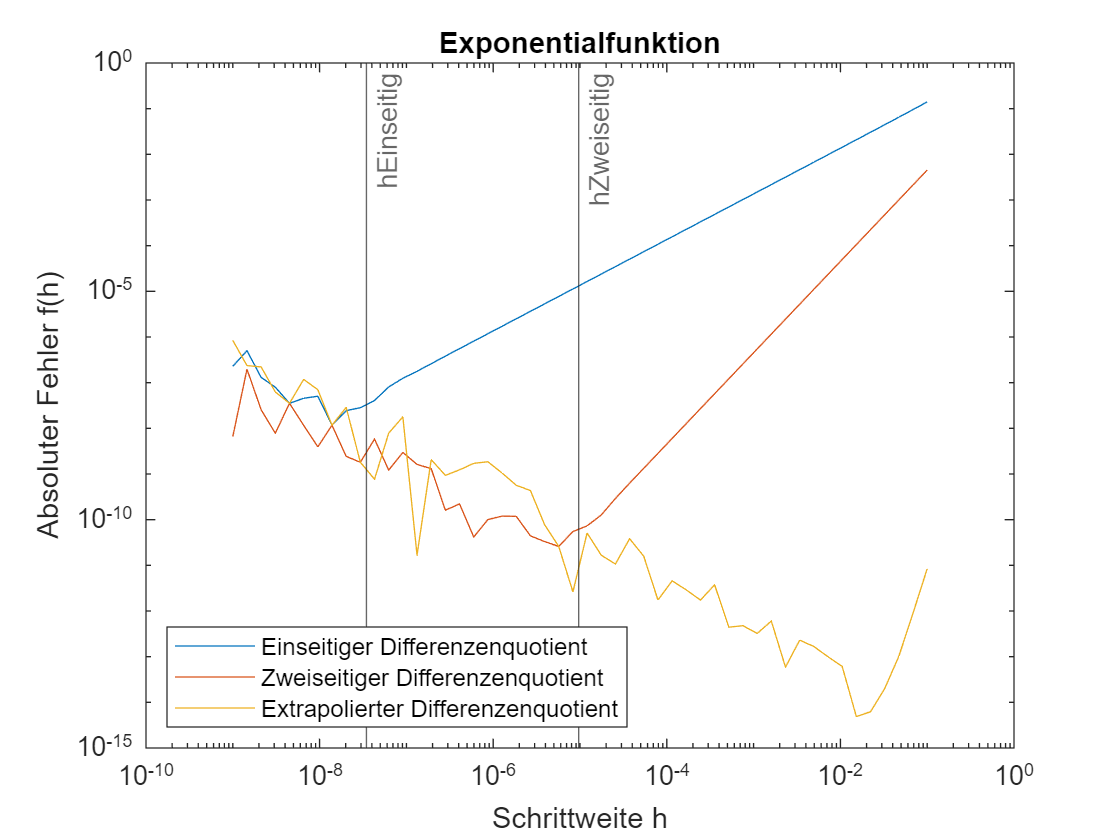

f = @func1;
fa = @func1Strich;

AbsFehlerEinseitig = FehlerEinseitigerDifferenzenquotient(f,fa,h,x);
AbsFehlerZweiseitig = FehlerZweiseitigerDifferenzenquotient(f,fa,h,x);
AbsFehlerExtrapoliert = FehlerExtrapolierterDifferenzenquotient(f,fa,h,x);

loglog(h,AbsFehlerEinseitig)
hold on 
loglog(h,AbsFehlerZweiseitig)
loglog(h,AbsFehlerExtrapoliert)
xline(hEinseitig,'-',{'hEinseitig'});
xline(hZweiseitig,'-',{'hZweiseitig'});
title('Exponentialfunktion')
legend({'Einseitiger Differenzenquotient', 'Zweiseitiger Differenzenquotient', 'Extrapolierter Differenzenquotient'},'Location','southwest')
ylabel('Absoluter Fehler f(h)')
xlabel('Schrittweite h')
hold off

## Logrithmus

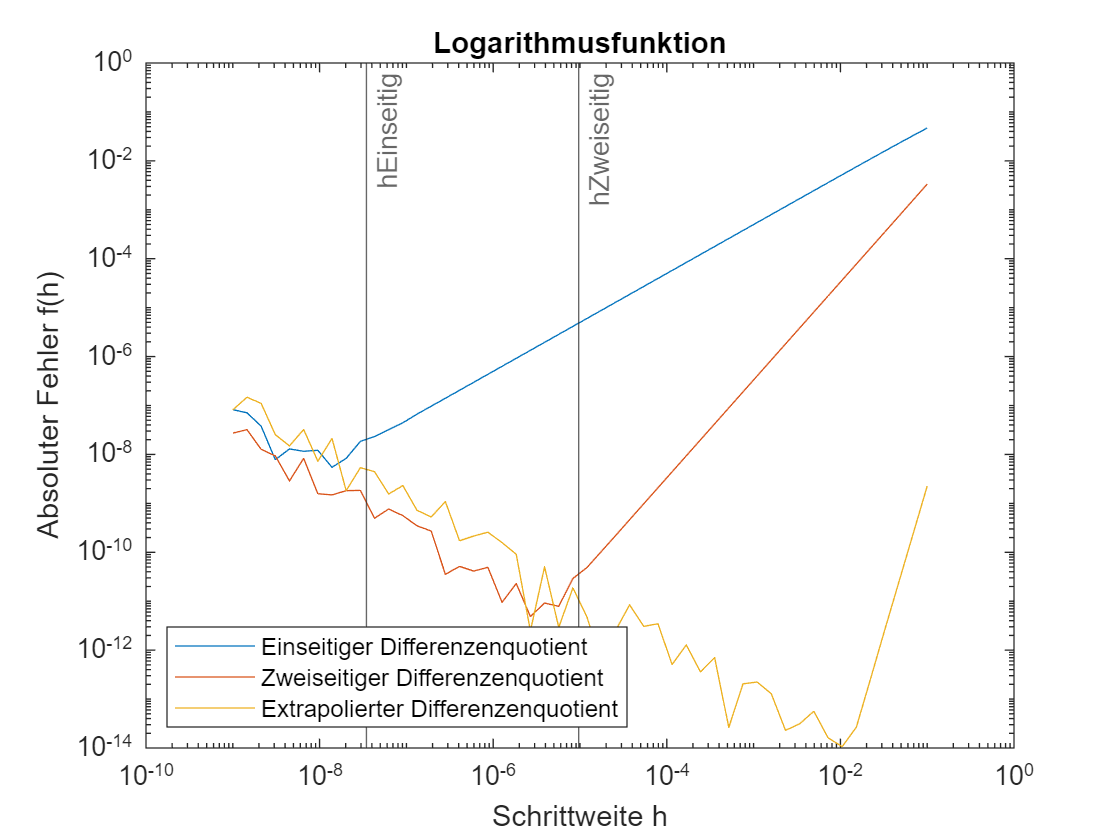

f = @func2;
fa = @func2Strich;

AbsFehlerEinseitig = FehlerEinseitigerDifferenzenquotient(f,fa,h,x);
AbsFehlerZweiseitig = FehlerZweiseitigerDifferenzenquotient(f,fa,h,x);
AbsFehlerExtrapoliert = FehlerExtrapolierterDifferenzenquotient(f,fa,h,x);

loglog(h,AbsFehlerEinseitig)
hold on 
loglog(h,AbsFehlerZweiseitig)
loglog(h,AbsFehlerExtrapoliert)
xline(hEinseitig,'-',{'hEinseitig'});
xline(hZweiseitig,'-',{'hZweiseitig'});
title('Logarithmusfunktion')
legend({'Einseitiger Differenzenquotient', 'Zweiseitiger Differenzenquotient', 'Extrapolierter Differenzenquotient'},'Location','southwest')
ylabel('Absoluter Fehler f(h)')
xlabel('Schrittweite h')
hold off

## Numerische Funktionen für die Differentation

Unsere Funktionen für die Berechnung des Absoluten Fehlers der einzelenen numerischen Ableitungsfunktionen

function output = FehlerEinseitigerDifferenzenquotient(g,ga,h,x)
    output = abs(EinseitigerDifferenzenquotient(g,h,x)-ga(x));
end

function output = FehlerZweiseitigerDifferenzenquotient(g,ga,h,x)
    output = abs(ZweiseitigerDifferenzenquotient(g,h,x)-ga(x));
end

function output = FehlerExtrapolierterDifferenzenquotient(g,ga,h,x)
    output = abs(ExtrapolierterDifferenzenquotient(g,h,x)-ga(x));
end

Als nächstes Definieren wir die einzelnen Numerischen Ableitungsfunktionen.

function output = EinseitigerDifferenzenquotient(g,h,x)
    output = (g(x+h)-g(x))./h; 
end

function output = ZweiseitigerDifferenzenquotient(g,h,x)
    output = (g(x+h)-g(x-h))./(2*h); 
end

function output = ExtrapolierterDifferenzenquotient(g,h,x)
    output = 1/45*(ZweiseitigerDifferenzenquotient(g,h,x)- ...
            20*ZweiseitigerDifferenzenquotient(g,h/2,x) + ...
            64*ZweiseitigerDifferenzenquotient(g,h/4,x));
end

## Formeln Expotnetialfunktion

Für die folgende Berechnung defnieren wie die Funktion die wir ableiten wollen, als auch unsere analytisch abgeleitet Version der Funktion.

function output = func1(x)
    output = exp(x);
end

function output = func1Strich(x)
    output = exp(x);
end


## Formeln Logrithmusfunktion

function output = func2(x)
    output = log(x);
end

function output = func2Strich(x)
    output = x.^(-1);
end

## Formeln Polynomfunktion

function output = func3(x)
    output = x.^8;
end

function output = func3Strich(x)
    output = 8*x.^7;
end

## Diskusion

Bei allen drei Testfunktionen (Polynomfunktion, Exponentialfunktion, Logarithmusfunktion) kann festgestellt werden, dass die optimalen Werte für hEinseitig und hZweiseitig nahe der experimentell ermittelten Minima sind. In weiterer Folge könnte für den extrapolierten Differenzenquotienten auch eine optimale Schrittweite ermittelt werden, welche nach den ermittelten Plots sind in einer Größenordnung von 0,01 befinden sollte. Weiters ist klar erkennbar, dass die erweiterten Alogrithmen für numerische Differentation bessere Ergebnisse liefern.